Ok keine Ahnung wie das hier geht. Hier ist grob was aus der 2. GÜ von MM1:

Definition Simulationsparameter:

clear; % clear var space

% Mechanische Parameter
d = 20;                 % Mechanische Dämpfung in Ns/m
k = 10000;              % Federsteifigkeit in N/m
m = 0.5;                % Gesamtmasse in kg

% Elektrische Parameter
l_L_0 = 0.0125;         % Länge des Anfangs-Luftspalts in m
l_Fe = 0.1;             % Mittlere Weglänge im Eisen in m 
mu_0 = 4 * pi * 10^-7;  % Magnetische Feldkonstante in Vs/Am
mu_r_Fe = 1000;         % relative Permeabilitätszahl Eisen
mu_r_L = 1;             % relative Permeabilitätszahl Luft
A = 1.69 * 10^-5;       % Effektive Polfläche in m^2
N = 12000;              % Wicklungszahl
F_test = 10;
L = 0.1218;             % Induktivität in Henry
R = 12;                 % Elektrischer Widerstand in Ohm
k_m = 25;               % Konstante kennlinienbeeinflusster Magnet in N/A
U_a = 24;               % Eingangsspannung Elektromagnet in V
U_test = 24;

% Abgeleitete Parameter
mu_L = mu_0 * mu_r_L;   % Permeabilität Luft in Vs/Am
mu_Fe = mu_0 * mu_r_Fe;  % Permeabilität Eisen in Vs/Am


% run simulation
sim("test_Simulink");

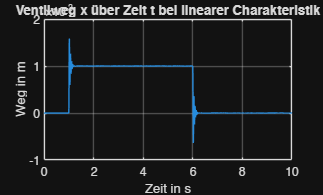


% display results
figure1 = figure('Name','Ventilweg x über Zeit t bei linearer Charakteristik');
plot(ans.simout_x.time, ans.simout_x.signals.values);
ylabel('Weg in m');
xlabel('Zeit in s');
title('Ventilweg x über Zeit t bei linearer Charakteristik');
grid on;